close all
clear all

load sstoi.indices.txt %para subir hay que comentar el texto

disp(sstoi_indices)

   1.0e+03 *

    1.9820    0.0010    0.0243   -0.0002    0.0258    0.0002    0.0280   -0.0002    0.0267    0.0001
    1.9820    0.0020    0.0254   -0.0007    0.0263   -0.0001    0.0280   -0.0001    0.0265   -0.0002
    1.9820    0.0030    0.0252   -0.0014    0.0269   -0.0003    0.0282   -0.0001    0.0271   -0.0001
    1.9820    0.0040    0.0246   -0.0012    0.0275   -0.0001    0.0286    0.0001    0.0278    0.0000
    1.9820    0.0050    0.0240   -0.0006    0.0277    0.0005    0.0292    0.0004    0.0284    0.0005
    1.9820    0.0060    0.0229   -0.0003    0.0271    0.0005    0.0295    0.0006    0.0284    0.0006
    1.9820    0.0070    0.0221    0.0002    0.0261    0.0003    0.0288   -0.0000    0.0276    0.0003
    1.9820    0.0080    0.0217    0.0008    0.0261    0.0008    0.0287    0.0000    0.0278    0.0009
    1.9820    0.0090    0.0219    0.0013    0.0265    0.0015    0.0289    0.0002    0.0280    0.0012
    1.9820    0.0100    0.0227    0.0018    0.0270    0.0020    0.0291    0.0

Importar datos: otra solución, aquí no es necesario comentar el texto

Definir las variables

year=sstoi_indices(:,1)

year =         1982
        1982
        1982
        1982
        1982
        1982
        1982
        1982
        1982
        1982


month=sstoi_indices(:,2)

month =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


R_1_2=sstoi_indices(:,3)

R_1_2 =    24.2800
   25.3800
   25.2200
   24.5700
   24.0000
   22.8800
   22.0700
   21.7100
   21.9100
   22.6700


R_3_4=sstoi_indices(:,9)

R_3_4 =    26.6500
   26.5400
   27.0900
   27.8300
   28.3700
   28.3500
   27.5700
   27.7600
   28.0100
   28.5000


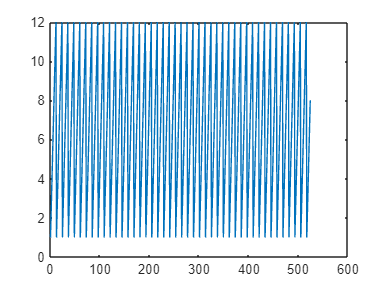

plot(month)

%[n m]=size[year]
n=length(year)

n = 524

day=ones(n,1)

day =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


date=datenum(year, month,day)

date =       723912
      723943
      723971
      724002
      724032
      724063
      724093
      724124
      724155
      724185


%Corroborar
datevec(date)

ans =         1982           1           1           0           0           0
        1982           2           1           0           0           0
        1982           3           1           0           0           0
        1982           4           1           0           0           0
        1982           5           1           0           0           0
        1982           6           1           0           0           0
        1982           7           1           0           0           0
        1982           8           1           0           0           0
        1982           9           1           0           0           0
        1982          10           1           0           0           0


Plotear

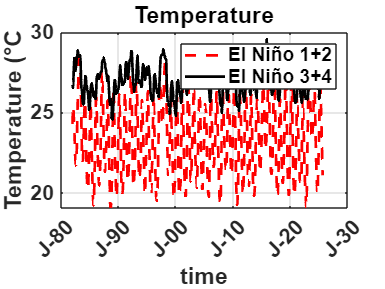

figure
plot(date,R_1_2,'r--',LineWidth=2)
hold on
plot(date,R_3_4,'k-',LineWidth=2)
title('Temperature')
xlabel('time')
ylabel('Temperature (°C')
set(gca,'fontsize',16,'fontweight','b')
legend('El Niño 1+2','El Niño 3+4')
datetick('x','m-yy')
grid on